%Find first n Hermite polynomials, H0=H(1),...
syms y

%y is the dimensionless position @y=sqrt(m*w/h)*x


n=20;
%k=mw/h
k=1000;
Hermites=sym(zeros(1,n));
%A=sqrt(m*w/(pi*h))*(2^n*n!)^(-1/2)
A=(k/pi)^(-1/4)*(2.^(0:n-1).*factorial(0:n-1)).^(-1/2);

E=(1:n)-1/2;

Hermites(1)=1;
Hermites(2)=2*y;
%H_n(y)=2*y*H_(n-1)(y)-2*(n-2)*H_(n-2)(y)
%So knowing first 2 Hermite polynomials allows us to
%   calculate others
for ii=3:length(Hermites)
    Hermites(ii)=2*y*Hermites(ii-1)-2*(ii-2)*Hermites(ii-2);
end

%Y_n(y)=A(n)*Hermites(n)*exp(-y^2/2)
%epsilon=2*n+1 where epsilon is the dimensionless energy and
%   equals to E(n)/(hw/2)
f=A.*Hermites.*exp(-y^2/2);

P=f.^2;

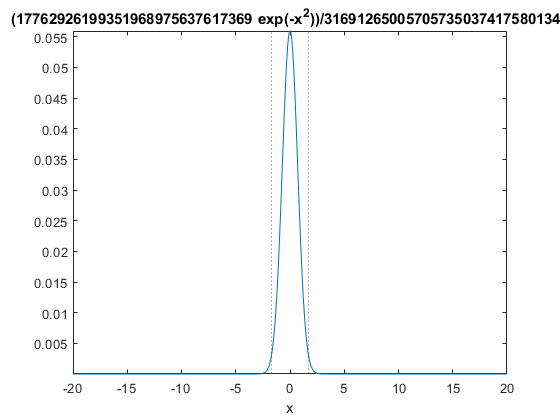

m=1;
classturnpoint=(2*m+1)^(1/2);
ezplot(P(m),[-20 20])
axis tight
hold on
xline(classturnpoint,':');
xline(-classturnpoint,':');
hold off

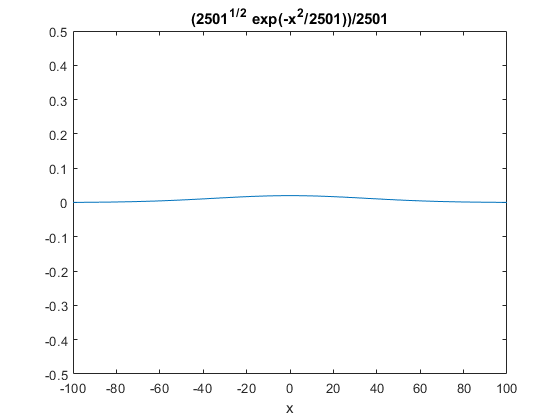

%Evolution of Gaussian wave packet

clear
syms x
for T=1:50
    P=1/(sqrt(1+T^2))*exp(-x^2/(1+T^2));
    ezplot(P,[-100 100])
    axis([-100 100 -.5 .5])
    pause(.2)
end

n=5;

a=sym(zeros(n));

for ii=2:n
    a(ii-1,ii)=sqrt(ii);
end

a;

$$a = \left(\begin{array}{ccccc} 0 & \sqrt{2} & 0 & 0 & 0\\ 0 & 0 & \sqrt{3} & 0 & 0\\ 0 & 0 & 0 & 2 & 0\\ 0 & 0 & 0 & 0 & \sqrt{5}\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

a';

$$ans = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ \sqrt{2} & 0 & 0 & 0 & 0\\ 0 & \sqrt{3} & 0 & 0 & 0\\ 0 & 0 & 2 & 0 & 0\\ 0 & 0 & 0 & \sqrt{5} & 0 \end{array}\right)$$

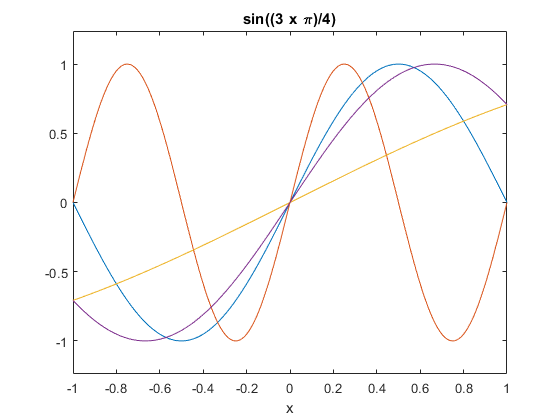

clear
hold off

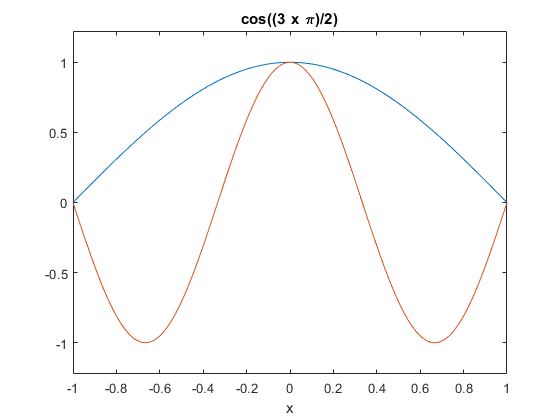

syms x

for n=[1 3]
    ezplot(cos(n*pi*x/2),[-1 1])
    hold on
end
hold off

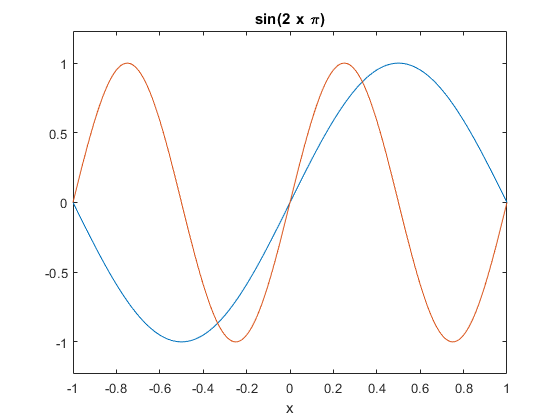

for n=[2 4]
    ezplot(sin(n*pi*x/2),[-1 1])
    hold on
end
hold off

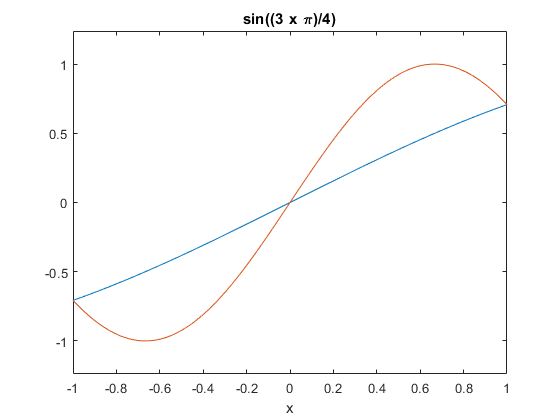

for n=[.5 1.5]
    ezplot(sin(n*pi*x/2),[-1 1])
    hold on
end

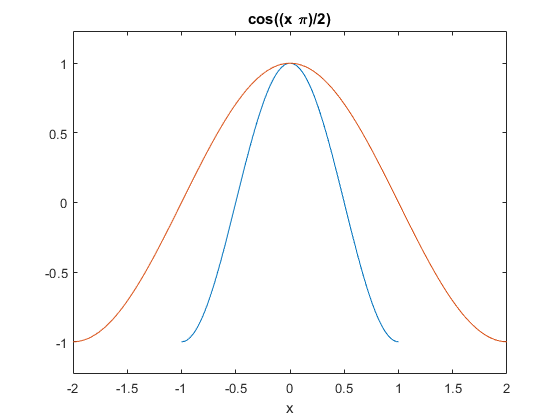

hold off

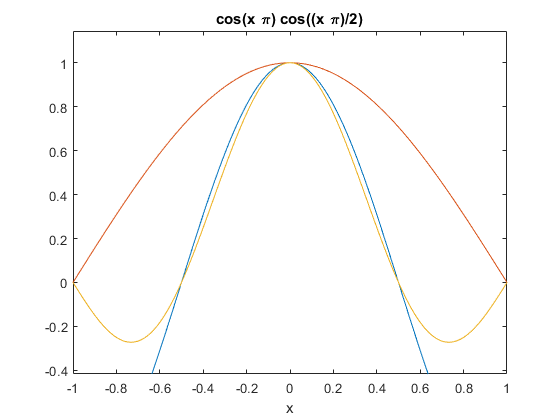

syms x

ezplot(cos(pi*x),[-1 1])
    hold on
ezplot(cos(pi*x/2),[-2 2])
ezplot(cos(pi*x)*cos(pi*x/2),[-1 1])

clear
close

syms x k a d k0 real
a=2;
d=50;
k0=1;

k0 = 1

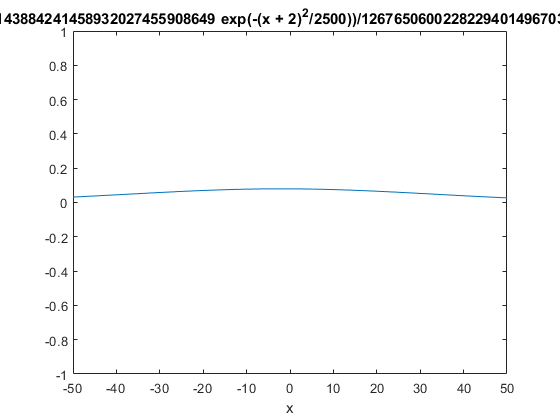



fx=(pi*d)^(-1/4)*exp(-(x+a)^2/(2*d^2))*exp(1i*k0*(x+a));
fk=int(fx*exp(1i*k*x), -inf, inf)*(2*pi)^(-1/2);

P=fx*fx';
Pk=fk*fk';
ezplot(P,[-50 50 -1 1])

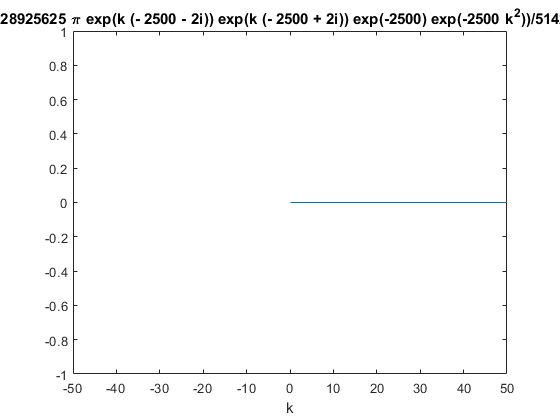

ezplot(Pk, [-50 50 -1 1])

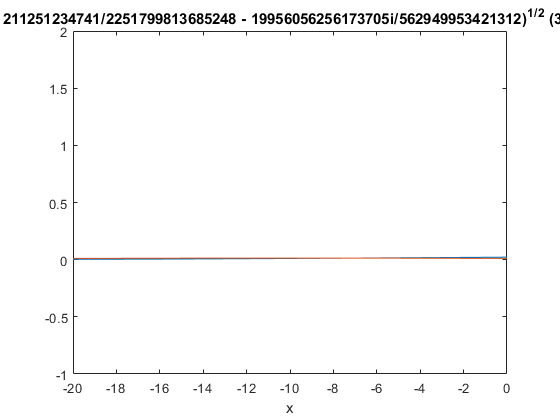

clear
close
syms x h t a m d k real

fxt=(pi^(1/2)*(d+1i*h*t/(m*d)))^(-1/2)*exp(-(x+a-h*k*t/m)^2/(2*d^2*(1+1i*h*t/(m*d^2))))*exp(1i*k*(x+a-h*k*t/(2*m)));
P=fxt*fxt';
P=subs(P,[h a m d k],[1 10 1 1 1]);

A=.7;
frxt=A*(pi^(1/2)*(d+1i*h*t/(m*d)))^(-1/2)*exp(-(x-a+h*k*t/m)^2/(2*d^2*(1+1i*h*t/(m*d^2))))*exp(-1i*k*(x-a+h*k*t/(2*m)));
PR=frxt*frxt';

PR=subs(PR,[h a m d k],[1 10 1 1 1]);

for ii=0:20
    Pk=subs(P,t,ii);
    ezplot(Pk,[-20 0 -1 2])
    hold on
    Pk=subs(PR,t,ii);
    ezplot(Pk,[-20 0 -1 2])
    pause(.1)
    hold off
end

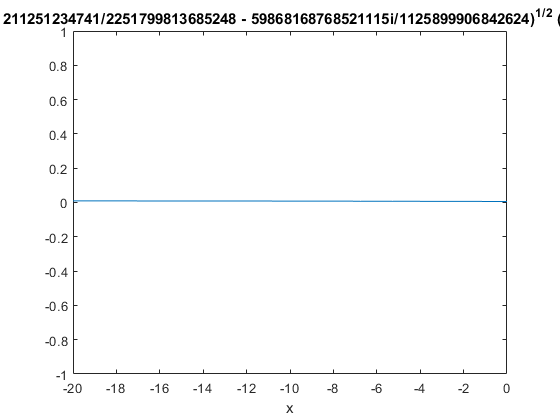

A=.7;
frxt=A*(pi^(1/2)*(d+1i*h*t/(m*d)))^(-1/2)*exp(-(x-a+h*k*t/m)^2/(2*d^2*(1+1i*h*t/(m*d^2))))*exp(-1i*k*(x-a+h*k*t/(2*m)));
PR=frxt*frxt';

PR=subs(PR,[h a m d k],[1 10 1 1 1]);
for ii=0:30
    Pk=subs(PR,t,ii);
    ezplot(Pk,[-20 0 -1 1])
    pause(.1)
end

clear
syms h k1 t m k0 d v x a c real

ff=exp(-1i*h*k1^2*t/(2*m))*exp(-(k1-k0)^2*d^2/2)*exp(k1*a)*c*exp(1i*(k1^2-2*m*v/h^2)^(1/2)*x)

$$ff = c\,{\mathrm{e}}^{-\frac{h\,{k_{1}}^{2}\,t\,\mathrm{i}}{2\,m}}\,{\mathrm{e}}^{-\frac{d^{2}\,{\left(k_{0}-k_{1}\right)}^{2}}{2}}\,{\mathrm{e}}^{a\,k_{1}}\,{\mathrm{e}}^{x\,\sqrt{{k_{1}}^{2}-\frac{2\,m\,v}{h^{2}}}\,\mathrm{i}}$$

fff=int(ff,k1)

$$fff = \int c\,{\mathrm{e}}^{-\frac{h\,{k_{1}}^{2}\,t\,\mathrm{i}}{2\,m}}\,{\mathrm{e}}^{-\frac{d^{2}\,{\left(k_{0}-k_{1}\right)}^{2}}{2}}\,{\mathrm{e}}^{a\,k_{1}}\,{\mathrm{e}}^{x\,\sqrt{{k_{1}}^{2}-\frac{2\,m\,v}{h^{2}}}\,\mathrm{i}}\mathrm{d}k_{1}$$

%f=(d^2/4*pi^3)^(1/4)*

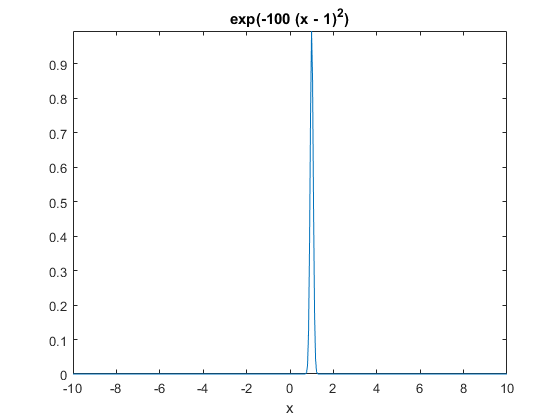

syms x real
k=1;
h=.1;
f=exp(-(x-k)^2/h^2);

ezplot(f,[-10 10])
axis tight